clear all
close all

%WORKING IN eV

v2=5e+9;
vx=1.8e+13; %18 TeV
M11=1000;
smin=0;
smax=pi/2;
a=1.45e-9;
r1=a;
r2=a;
hxmin=0.01;
hxmax=0.1;

h2eevno=zeros(1,100);
h2euvno=zeros(1,100);
h2etvno=zeros(1,100);
h2uevno=zeros(1,100);
h2uuvno=zeros(1,100);
h2utvno=zeros(1,100);
hx1vno=zeros(1,100);
hx2vno=zeros(1,100);
hx3vno=zeros(1,100);
ssno=zeros(1,100);
m1vno=zeros(1,100);
m2vno=zeros(1,100);
m3vno=zeros(1,100);

h2eevio=zeros(1,100);
h2euvio=zeros(1,100);
h2etvio=zeros(1,100);
h2uevio=zeros(1,100);
h2uuvio=zeros(1,100);
h2utvio=zeros(1,100);
hx1vio=zeros(1,100);
hx2vio=zeros(1,100);
hx3vio=zeros(1,100);
ssio=zeros(1,100);
m1vio=zeros(1,100);
m2vio=zeros(1,100);
m3vio=zeros(1,100);

k=0;
z=0;
zz=0;

tic
for i=1:70000000
    hx1=hxmin+rand*(hxmax-hxmin);
    hx2=hxmin+rand*(hxmax-hxmin);
    %hx3=hxmin+rand*(hxmax-hxmin);
    h2ee=rand;
    h2eu=rand;
    h2et=rand;
    h2ue=rand;
    h2uu=rand;
    h2ut=rand;
    

    p=hx1/hx2;
    mv=((M11*v2^2)/(hx1^2*vx^2))*[h2ee^2+(h2ue^2*p^2) h2ee*h2eu+h2ue*h2uu*p^2 h2ee*h2et+h2ue*h2ut*p^2 ; h2ee*h2eu+h2ue*h2uu*p^2 h2eu^2+h2uu^2*p^2 h2eu*h2et+h2uu*h2ut*p^2 ; h2ee*h2et+h2ue*h2ut*p^2 h2eu*h2et+h2uu*h2ut*p^2 h2et^2+h2ut^2*p^2];

    [v,g]=eig(mv);
    
    eigmass=[round(abs(g(1,1)),5);round(abs(g(2,2)),5);round(abs(g(3,3)),5)];
    
    %Choose scenarios with at least two massive neutrinos
    if (eigmass(2)<eigmass(3))

    
        if ((eigmass(3)<0.055) && (eigmass(2)<0.01))
            tt=0;
            if ((abs(v(1,1))>abs(v(2,1))) && (abs(v(2,1))>abs(v(3,1))))
                if (eigmass(3)>0.044)
                    tt=1;%NO
                end
            end
            if ((abs(v(2,1))>abs(v(3,1))) && (abs(v(3,1))>abs(v(1,1))))
                if (eigmass(2)>0.007)
                    tt=2;%IO
                end
            end

            s_emu=smin+rand*(smax-smin);
            
            
            Rl=[cos(s_emu) sin(s_emu) r1 ; -sin(s_emu) cos(s_emu) r2 ; -r1*cos(s_emu)+r2*sin(s_emu) -r2*cos(s_emu)-r1*sin(s_emu) 1];
            Upmns=Rl'*v;
            
            %Choose only acceptable values of pmns
             if (abs(Upmns(1,1))<(0.845) && (abs(Upmns(1,1))>(0.801)))
                
                if (abs(Upmns(1,2))<(0.579) && (abs(Upmns(1,2))>(0.513)))
                    
                    if (abs(Upmns(1,3))<(0.156) && (abs(Upmns(1,3))>(0.143)))
                        
                        if (abs(Upmns(2,1))<(0.507) && (abs(Upmns(2,1))>(0.233)))
                            
                            if (abs(Upmns(2,2))<(0.694) && (abs(Upmns(2,2))>(0.461)))
                                
                                if (abs(Upmns(2,3))<(0.778) && (abs(Upmns(2,3))>(0.631)))
                                    
                                    if (abs(Upmns(3,1))<(0.526) && (abs(Upmns(3,1))>(0.261)))
                                        
                                        if (abs(Upmns(3,2))<(0.701) && (abs(Upmns(3,2))>(0.471)))
                                            
                                            if (abs(Upmns(3,3))<(0.761) && (abs(Upmns(3,3))>(0.611)))
                                                if (tt==1)%choose between NO and IO
                                                    k=k+1;
                                                    h2eevno(k)=h2ee;
                                                    h2euvno(k)=h2eu;
                                                    h2etvno(k)=h2et;
                                                    h2uevno(k)=h2ue;
                                                    h2uuvno(k)=h2uu;
                                                    h2utvno(k)=h2ut;
                                                    hx1vno(k)=hx1;
                                                    hx2vno(k)=hx2;
                                                    %hx3vno(k)=hx3;
                                                    ssno(k)=s_emu;
                                                    m1vno(k)=g(1,1);
                                                    m2vno(k)=g(2,2);
                                                    m3vno(k)=g(3,3);
                                        
                                                end
                                
                                                if (tt==2)
                                                    z=z+1;
                                                    h2eevio(z)=h2ee;
                                                    h2euvio(z)=h2eu;
                                                    h2etvio(z)=h2et;
                                                    h2uevio(z)=h2ue;
                                                    h2uuvio(z)=h2uu;
                                                    h2utvio(z)=h2ut;
                                                    hx1vio(z)=hx1;
                                                    hx2vio(z)=hx2;
                                                    %hx3vio(z)=hx3;
                                                    ssio(z)=s_emu;
                                                    m1vio(z)=g(1,1);
                                                    m2vio(z)=g(2,2);
                                                    m3vio(z)=g(3,3);
                                                end
                                                
                                            end
                                        end
                                    end
                                end
                            end
                        end
                    end
                end
             end
        end
    
    else 
        zz=zz+1;
    end
    
end
toc

Elapsed time is 397.889058 seconds.


zz

zz = 0

h2eevno

h2eevno =     0.5634    0.7495    0.5150    0.4945    0.7488    0.5047    0.4772    0.3275    0.1769    0.2069    0.8531    0.7205    0.9654    0.6393    0.1038    0.9831    0.3906    0.0609    0.5614    0.2525    0.9089    0.2356    0.4724    0.5563    0.0189    0.6547    0.4283    0.3714    0.4930    0.7570    0.5509    0.1705    0.7523    0.0502    0.6861    0.3261    0.6903    0.1628    0.3509    0.3597    0.8007    0.3245    0.2810    0.2795    0.3569    0.4234    0.0183    0.6445    0.7126    0.6016


h2euvno

h2euvno =     0.5620    0.2266    0.3484    0.8854    0.8239    0.0583    0.4527    0.2286    0.5799    0.6514    0.7025    0.9965    0.6368    0.1404    0.4569    0.8591    0.0853    0.5050    0.7382    0.7724    0.9695    0.0101    0.9545    0.4803    0.4959    0.5768    0.8091    0.1698    0.1747    0.6003    0.5350    0.4120    0.6635    0.6715    0.4790    0.9935    0.4814    0.1067    0.3460    0.0512    0.7201    0.0658    0.7517    0.6801    0.1605    0.3800    0.7013    0.8431    0.1705    0.5326


h2etvno

h2etvno =     0.4698    0.9131    0.9355    0.6728    0.9134    0.7037    0.7785    0.4230    0.8456    0.8336    0.6375    0.4017    0.7480    0.7615    0.7759    0.7052    0.8428    0.6148    0.0473    0.7152    0.4050    0.3338    0.3173    0.8050    0.5751    0.5173    0.3155    0.5747    0.8540    0.9215    0.8897    0.2339    0.7506    0.8844    0.6825    0.8633    0.9339    0.3897    0.6254    0.6547    0.9529    0.4045    0.4545    0.4717    0.5175    0.7223    0.8647    0.2932    0.9160    0.9836


h2uevno

h2uevno =     0.5303    0.6362    0.6572    0.1677    0.5810    0.8531    0.6014    0.8350    0.3759    0.5957    0.6712    0.3805    0.5520    0.8343    0.2064    0.5651    0.8096    0.2148    0.0082    0.0160    0.5402    0.7379    0.5394    0.3676    0.1443    0.5377    0.2994    0.8635    0.3349    0.5357    0.6357    0.0093    0.3736    0.3119    0.3782    0.0094    0.8718    0.5674    0.3353    0.5485    0.7467    0.8194    0.1335    0.0982    0.6443    0.4958    0.5282    0.7344    0.9203    0.6663


h2uuvno

h2uuvno =     0.2830    0.8001    0.8321    0.6466    0.5548    0.3237    0.8014    0.9307    0.7717    0.8271    0.1344    0.2462    0.2583    0.4996    0.2856    0.2156    0.6145    0.8656    0.4585    0.3871    0.2220    0.2227    0.5175    0.3740    0.5830    0.1991    0.1959    0.9457    0.3573    0.4687    0.7363    0.5298    0.1605    0.7926    0.1745    0.3581    0.7947    0.8267    0.5177    0.3451    0.7445    0.4429    0.7803    0.3551    0.5250    0.8458    0.9204    0.5292    0.4225    0.7326


h2utvno

h2utvno =     0.9014    0.1395    0.4626    0.8966    0.8213    0.9231    0.6818    0.5160    0.7705    0.1507    0.9404    0.6141    0.6099    0.6597    0.1341    0.9893    0.8280    0.8936    0.5235    0.6386    0.9346    0.8121    0.9571    0.4398    0.5109    0.9722    0.7122    0.0849    0.1942    0.5816    0.8446    0.6215    0.6695    0.6787    0.5293    0.5681    0.8049    0.7571    0.3903    0.4525    0.7863    0.6866    0.8312    0.3623    0.5117    0.3298    0.4817    0.9374    0.9432    0.8658


hx1vno

hx1vno =     0.0506    0.0515    0.0552    0.0678    0.0900    0.0825    0.0496    0.0264    0.0644    0.0442    0.0750    0.0813    0.0920    0.0558    0.0417    0.0903    0.0746    0.0372    0.0946    0.0439    0.0836    0.0956    0.0743    0.0456    0.0364    0.0514    0.0576    0.0309    0.0507    0.0672    0.0680    0.0434    0.0616    0.0517    0.0453    0.0576    0.0563    0.0267    0.0418    0.0578    0.0705    0.0246    0.0588    0.0824    0.0392    0.0386    0.0476    0.0960    0.0698    0.0828


hx2vno

hx2vno =     0.0613    0.0702    0.0802    0.0634    0.0613    0.0555    0.0882    0.0931    0.0543    0.0856    0.0591    0.0361    0.0454    0.0699    0.0229    0.0611    0.0569    0.0903    0.0289    0.0739    0.0549    0.0445    0.0566    0.0847    0.0485    0.0671    0.0374    0.0983    0.0268    0.0617    0.0712    0.0366    0.0507    0.0685    0.0648    0.0967    0.0976    0.0578    0.0466    0.0368    0.0767    0.0759    0.0614    0.0226    0.0514    0.0829    0.0930    0.0569    0.0803    0.0660


hx3vno

hx3vno =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ssno

ssno =     1.1018    0.8897    1.0620    0.1908    0.9883    1.0240    0.9622    1.0691    0.1948    0.1623    0.9035    1.0284    1.2621    0.9790    0.2014    1.2361    1.1844    0.3872    0.3077    0.0718    1.1647    1.0703    0.8732    1.0662    0.3303    1.1569    0.9394    1.2362    1.1244    1.0874    0.9713    0.3351    1.1502    0.4235    1.1790    0.0958    1.1346    0.9089    0.8951    1.2722    1.0098    1.0450    0.0701    0.0884    1.1841    0.9786    0.3732    1.0707    0.9973    0.9786


m1vno

m1vno = 	1.0e+-17 *

    0.0818    0.0690    0.0609    0.7592    0.0326    0.2191   -0.2335    0.1716   -0.1598    0.4296   -0.3755   -0.0709   -0.0712   -0.1394    0.0000   -0.2351   -0.1353    0.2804    0.3253    0.2510   -0.1266   -0.1257   -0.3076   -0.1083    0.0849   -0.0044    0.0811    0.0946    0.1186   -0.0965    0.0891   -0.2775    0.0329   -0.2860   -0.2489   -0.2006    0.0130   -0.0590    0.0402    0.0219   -0.1452   -0.0281    0.0188    0.0626   -0.0425    0.1981    0.2525    0.2419    0.6252   -0.0780


m2vno

m2vno =     0.0030    0.0083    0.0039    0.0018    0.0002    0.0003    0.0009    0.0024    0.0007    0.0049    0.0037    0.0055    0.0006    0.0015    0.0066    0.0039    0.0023    0.0002    0.0047    0.0008    0.0073    0.0001    0.0050    0.0001    0.0006    0.0039    0.0089    0.0076    0.0076    0.0001    0.0003    0.0018    0.0022    0.0013    0.0004    0.0005    0.0008    0.0034    0.0016    0.0025    0.0001    0.0013    0.0012    0.0004    0.0021    0.0035    0.0032    0.0026    0.0004    0.0004


m3vno

m3vno =     0.0469    0.0504    0.0442    0.0470    0.0467    0.0505    0.0463    0.0515    0.0543    0.0522    0.0485    0.0485    0.0446    0.0454    0.0508    0.0447    0.0507    0.0505    0.0473    0.0539    0.0451    0.0503    0.0478    0.0490    0.0535    0.0480    0.0479    0.0456    0.0523    0.0475    0.0481    0.0470    0.0482    0.0539    0.0517    0.0460    0.0542    0.0535    0.0453    0.0460    0.0547    0.0515    0.0448    0.0486    0.0469    0.0524    0.0512    0.0481    0.0442    0.0484



h2eevio

h2eevio =     0.1843    0.1582    0.0175    0.3198    0.7965    0.9485    0.4612    0.9604    0.0476    0.4196    0.7494    0.1269    0.9872    0.9324    0.9737    0.6780    0.4068    0.8243    0.8765    0.0359    0.7841    0.2455    0.0015    0.4289    0.1412    0.3633    0.8411    0.5688    0.8526    0.2505    0.1233    0.1440    0.2370    0.5191    0.2316    0.1460    0.1067    0.9612    0.1673    0.8777    0.5194    0.1120    0.2138    0.8878    0.9671    0.6236    0.1999    0.0094    0.3830    0.0432


h2euvio

h2euvio =     0.5683    0.5815    0.2826    0.3369    0.4467    0.1978    0.2316    0.2202    0.2611    0.1385    0.2644    0.5739    0.3888    0.4512    0.6780    0.3900    0.0500    0.0252    0.3980    0.4341    0.1103    0.2837    0.5673    0.6010    0.2323    0.4734    0.2374    0.0245    0.0127    0.3872    0.2109    0.6193    0.2064    0.0573    0.5389    0.2227    0.3885    0.1353    0.7398    0.0512    0.5007    0.3454    0.5623    0.3873    0.3046    0.1104    0.4269    0.6452    0.4673    0.2437


h2etvio

h2etvio =     0.9337    0.9939    0.8573    0.7559    0.2406    0.6873    0.1089    0.2592    0.6994    0.0473    0.2818    0.9776    0.3632    0.1961    0.3128    0.4072    0.1068    0.6199    0.4498    0.8393    0.4131    0.8448    0.9936    0.9621    0.2900    0.9929    0.1930    0.0344    0.0043    0.7164    0.6244    0.9934    0.5122    0.0150    0.9881    0.3554    0.9693    0.0687    0.9013    0.1048    0.9149    0.9319    0.9247    0.2727    0.2491    0.3631    0.8486    0.9990    0.9281    0.4919


h2uevio

h2uevio =     0.8809    0.8838    0.9196    0.9506    0.2047    0.0457    0.1319    0.0543    0.6481    0.4808    0.0941    0.9549    0.0259    0.0821    0.2754    0.0680    0.1007    0.0367    0.1120    0.9250    0.1072    0.9982    0.7068    0.2849    0.9241    0.8895    0.3361    0.2289    0.5306    0.3792    0.5790    0.9509    0.7748    0.1306    0.5909    0.9839    0.8365    0.3507    0.9042    0.1209    0.4885    0.6152    0.7657    0.1155    0.3215    0.1933    0.6538    0.8952    0.7395    0.8670


h2uuvio

h2uuvio =     0.2467    0.1250    0.2632    0.0551    0.5557    0.3864    0.5645    0.1201    0.2327    0.4518    0.5762    0.3771    0.5384    0.4487    0.7130    0.3901    0.3397    0.3297    0.4714    0.1278    0.2851    0.1767    0.1017    0.0799    0.4277    0.1253    0.5290    0.3271    0.4976    0.0806    0.0844    0.3676    0.1967    0.3262    0.2215    0.2329    0.2500    0.6006    0.6722    0.4550    0.0211    0.2401    0.2190    0.5011    0.4636    0.4496    0.0901    0.4760    0.0943    0.1230


h2utvio

h2utvio =     0.0201    0.5223    0.5874    0.4359    0.7611    0.7739    0.8808    0.3640    0.0657    0.9669    0.9941    0.4531    0.8772    0.7238    0.9063    0.9792    0.9490    0.9884    0.8739    0.6489    0.8872    0.3536    0.1779    0.0629    0.1389    0.4839    0.8831    0.6197    0.9100    0.2112    0.1778    0.2574    0.2351    0.9767    0.2723    0.0241    0.2587    0.9813    0.1084    0.8063    0.0611    0.3886    0.1684    0.7800    0.7135    0.8539    0.4061    0.0981    0.2977    0.6459


hx1vio

hx1vio =     0.0774    0.0808    0.0656    0.0433    0.0633    0.0545    0.0395    0.0735    0.0599    0.0298    0.0555    0.0739    0.0746    0.0840    0.0794    0.0392    0.0318    0.0428    0.0682    0.0630    0.0417    0.0529    0.0988    0.0525    0.0166    0.0625    0.0589    0.0438    0.0644    0.0472    0.0503    0.0700    0.0323    0.0454    0.0605    0.0238    0.0741    0.0774    0.0502    0.0708    0.0494    0.0648    0.0610    0.0684    0.0739    0.0358    0.0549    0.0802    0.0504    0.0384


hx2vio

hx2vio =     0.0750    0.0424    0.0597    0.0570    0.0533    0.0524    0.0710    0.0288    0.0585    0.0496    0.0843    0.0744    0.0759    0.0579    0.0521    0.0631    0.0795    0.0739    0.0567    0.0598    0.0625    0.0632    0.0627    0.0208    0.0706    0.0549    0.0478    0.0420    0.0534    0.0203    0.0431    0.0733    0.0481    0.0869    0.0424    0.0897    0.0570    0.0726    0.0835    0.0720    0.0353    0.0331    0.0559    0.0622    0.0379    0.0575    0.0393    0.0798    0.0468    0.0553


hx3vio

hx3vio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ssio

ssio =     0.9926    1.4942    0.9386    1.4153    0.8919    1.3542    0.9333    0.9265    0.6980    0.7552    1.1374    1.0558    1.0762    0.8822    0.7971    0.7149    0.9937    1.2333    0.9919    1.4005    1.1124    0.9779    1.2206    1.0482    0.9216    1.3665    1.0446    1.1947    1.2157    1.3544    1.0237    0.9598    0.9391    0.9467    1.0706    0.9975    0.8943    1.1057    0.6109    1.2600    1.2183    0.8812    1.0239    1.0130    1.0183    1.3597    1.3696    0.7725    1.2745    1.4371


m1vio

m1vio = 	1.0e+-16 *

    0.0125   -0.1148   -0.0304   -0.0210    0.1049    0.0186   -0.0066   -0.0070   -0.0117   -0.0178   -0.0187   -0.0205   -0.0033    0.0257   -0.0231    0.0048    0.0120    0.0009   -0.0194   -0.0079    0.0210   -0.0217   -0.0033   -0.0260    0.0536    0.0075    0.0290    0.0260    0.0336    0.0168   -0.0205    0.0099   -0.0163   -0.0102    0.0096    0.0453   -0.0495   -0.0098    0.0117   -0.0136    0.1204   -0.0724    0.0097   -0.0063   -0.0541   -0.0181    0.0685    0.0427    0.0614    0.0186


m2vio

m2vio =     0.0089    0.0087    0.0076    0.0086    0.0070    0.0096    0.0073    0.0080    0.0083    0.0094    0.0077    0.0070    0.0081    0.0074    0.0071    0.0098    0.0082    0.0084    0.0076    0.0086    0.0095    0.0092    0.0076    0.0082    0.0077    0.0072    0.0095    0.0099    0.0096    0.0078    0.0074    0.0091    0.0077    0.0086    0.0078    0.0071    0.0093    0.0086    0.0086    0.0093    0.0091    0.0081    0.0098    0.0078    0.0073    0.0087    0.0085    0.0093    0.0089    0.0072


m3vio

m3vio =     0.0184    0.0532    0.0342    0.0498    0.0354    0.0481    0.0235    0.0207    0.0145    0.0508    0.0246    0.0290    0.0235    0.0216    0.0513    0.0510    0.0180    0.0517    0.0352    0.0366    0.0433    0.0366    0.0134    0.0493    0.0527    0.0460    0.0479    0.0270    0.0407    0.0540    0.0218    0.0287    0.0422    0.0126    0.0404    0.0295    0.0258    0.0247    0.0480    0.0158    0.0488    0.0517    0.0318    0.0263    0.0525    0.0460    0.0457    0.0202    0.0510    0.0385


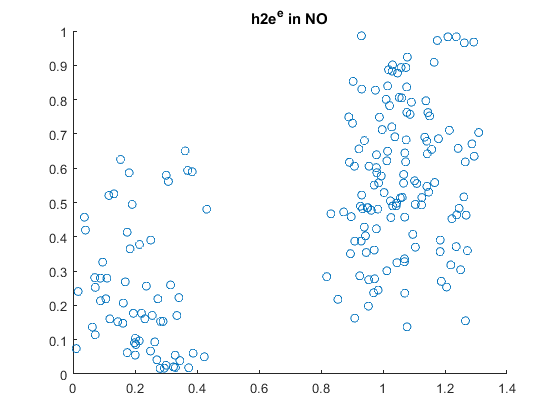


scatter(ssno,h2eevno)
title('h2e^e in NO')

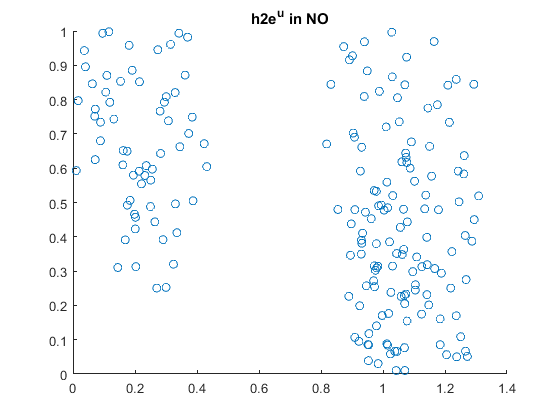


scatter(ssno,h2euvno)
title('h2e^u in NO')

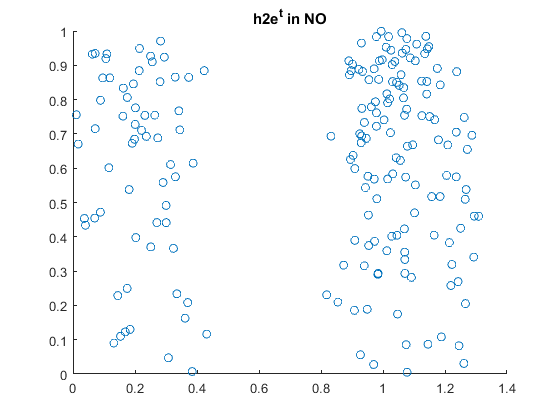


scatter(ssno,h2etvno)
title('h2e^t in NO')

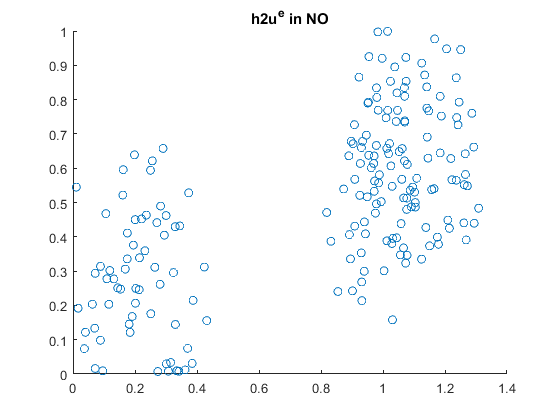


scatter(ssno,h2uevno)
title('h2u^e in NO')

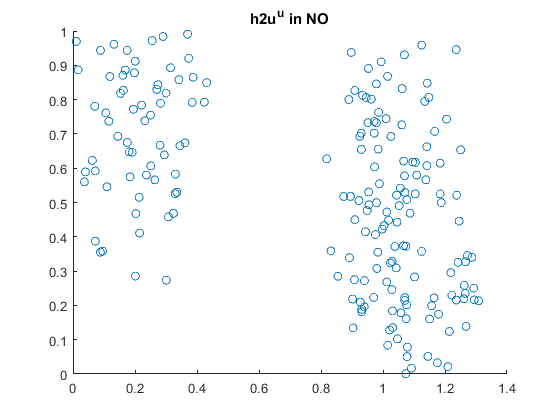


scatter(ssno,h2uuvno)
title('h2u^u in NO')

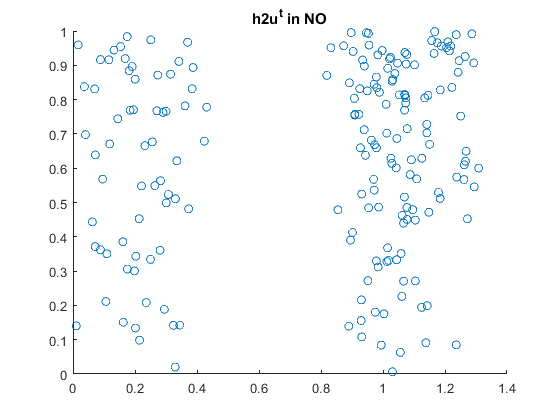


scatter(ssno,h2utvno)
title('h2u^t in NO')

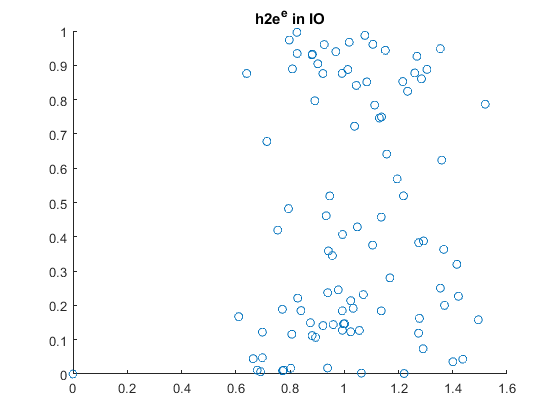



scatter(ssio,h2eevio)
title('h2e^e in IO')

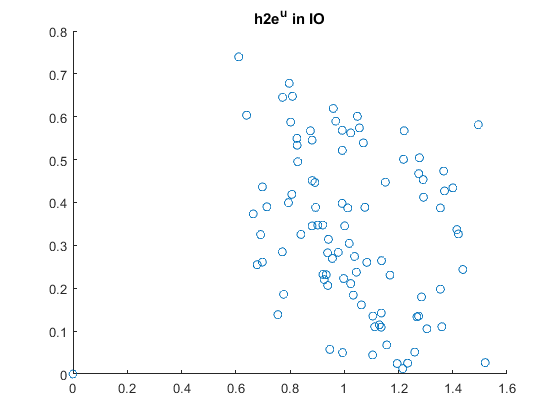


scatter(ssio,h2euvio)
title('h2e^u in IO')

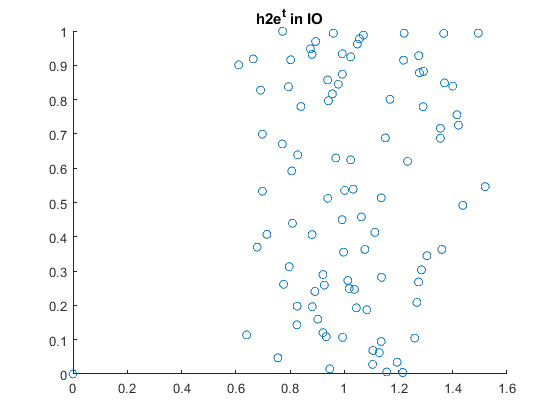


scatter(ssio,h2etvio)
title('h2e^t in IO')

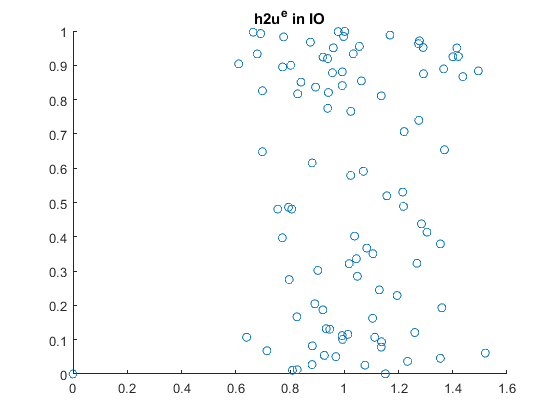


scatter(ssio,h2uevio)
title('h2u^e in IO')

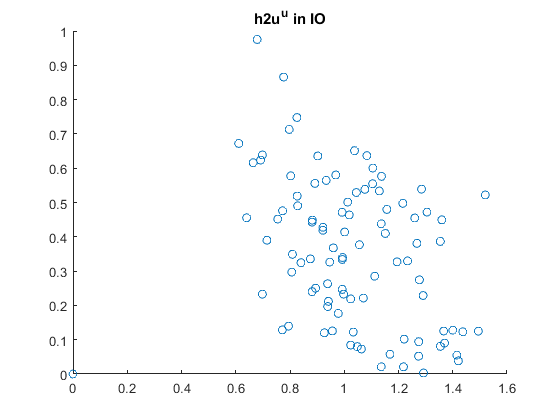


scatter(ssio,h2uuvio)
title('h2u^u in IO')

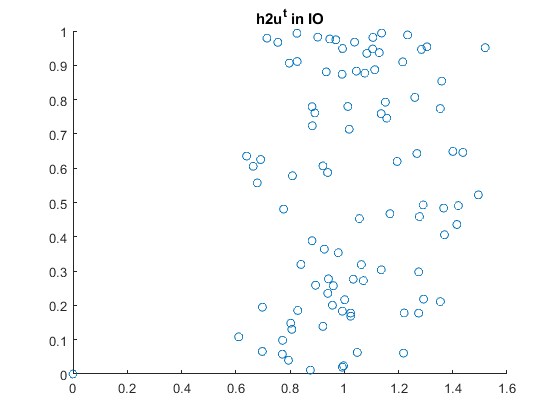


scatter(ssio,h2utvio)
title('h2u^t in IO')